# Trend Trading Staregy on Equity 

**Clear and cleaning workspace**

clear ; clc;

## **Load Data**

Data Loading

pricedata = readtimetable ("Trend Trading Input Output Data.xlsx","Sheet", "Price Data");

volumedata = readtimetable ("Trend Trading Input Output Data.xlsx","Sheet", "Volume Data");

indexbenchmark = readtimetable ("Trend Trading Input Output Data.xlsx","Sheet", "IHSG Data");


Data Cleaning 

pricedata = fillmissing (pricedata, "previous");
volumedata = fillmissing (volumedata, "previous");
indexbenchmark = fillmissing (indexbenchmark, "previous");

## Inspect Data Set

symbols = string(pricedata.Properties.VariableNames);
head (pricedata)

ans = 8×665 timetable
       Time        AALI     ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS     AHAP     AIMS    AISA    AKKU    AKPI    AKRA    AKSI     ALDO     ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    APIC


% Visualize the performance of each stock over the range of price data.
returns = tick2ret (pricedata);

returns = 853×665 timetable
       Time           AALI         ABBA       ABDA       ABMM         ACES          ACST          ADES          ADHI          ADMF          ADMG          ADRO       AGAR       AGII          AGRO          AGRS         AHAP         AIMS          AISA         AKKU         AKPI          AKRA          AKSI       ALDO       ALKA          ALMI          ALTO         AMAG       AMAN    AMAR       AMFG          AMIN       AMOR

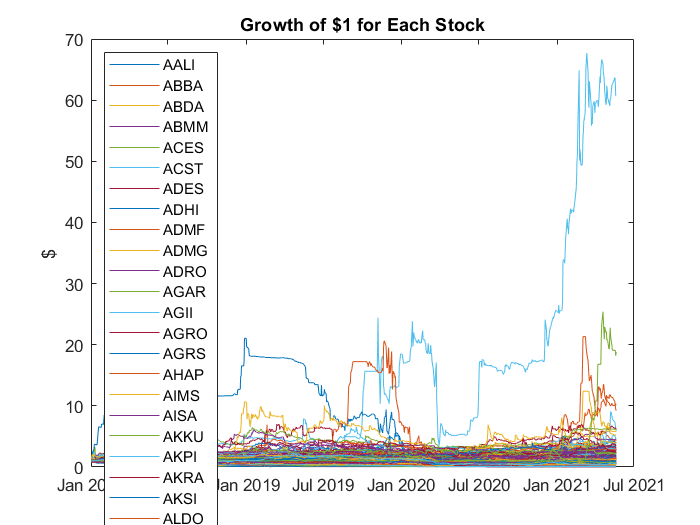

totalRet = ret2tick(returns);   
plot(totalRet.Time,totalRet.Variables);
legend(symbols,'Location','NW');
title('Growth of $1 for Each Stock')
ylabel('$')

## Build Signal Table

###     Value Signal

        Value Threshold      

valuedata = pricedata;
valuedata.Variables = (pricedata.Variables) .* (volumedata.Variables);
% head(valuedata)
valuethreshold = 20e+9 % tag input parameter

valuethreshold = 2.0000e+10

valuesignal = valuedata;
valuesignal.Variables = double(valuedata.Variables > valuethreshold);

head (valuesignal)

ans = 8×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    APIC

clearvars valuedata valuethreshold


### Volume SIgnal

        Volume Threshold

        Non - liquid symbol excluder 

volumethreshold = 1e+5 % tag input parameter

volumethreshold = 100000

volumehigherthreshold = volumedata;
volumehigherthreshold.Variables = double (volumedata.Variables > volumethreshold);
volumesignthresholdwindow = 40; % tag input parameter n days to avoid pump and dump and non liquid stocks
volumesignal = volumedata;
volumesignal.Variables = double(movmin (volumehigherthreshold.Variables, volumesignthresholdwindow));
head (volumesignal)

ans = 8×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    APIC

clearvars volumehigherthreshold volumethreshold


### Price Signal

        SMA Signal

smaWindow = 20 % tag input parameter

smaWindow = 20

smaprice = movavg (pricedata, 'simple', smaWindow);
smasignal = pricedata;

smasignal.Variables = double (pricedata.Variables > smaprice.Variables);
head (smasignal)

ans = 8×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    APIC

clearvars smaprice smaWindow

**Buffer Signal for SMA Signal**

buffersignalwindow = 8; % tag input parameter
buffersmasignal = pricedata;
buffersmasignal.Variables = double(movmax (smasignal.Variables,buffersignalwindow));

head(buffersmasignal)

ans = 8×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    APIC

clearvars smasignal

**    Combined Signal **

combinedsignal = pricedata;
combinedsignal.Variables = valuesignal.Variables .* volumesignal.Variables .*buffersmasignal.Variables;
head (combinedsignal)

ans = 8×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    APIC

**Cut Loss Signal**

        10 Days Minimum Return 

lagshortershift = 10; % tag input parameter

lagshortprice = pricedata;
templagshorterprice = lagshortprice.Variables; 
templagshorterprice(1:lagshortershift ,:) = NaN;
lagshortprice.Variables = templagshorterprice; 
lagshortprice (lagshortershift +1:end,:) = pricedata(1:end-lagshortershift ,:);

cutloss10dayreturn = pricedata;
cutloss10dayreturn.Variables = pricedata.Variables ./ lagshortprice.Variables;
cutloss10dayreturn.Variables = cutloss10dayreturn.Variables - 1;

cutloss10daythreshold = -0.15;
cutloss10daysignal = pricedata;

cutloss10daysignal.Variables = double (cutloss10dayreturn.Variables > cutloss10daythreshold)

cutloss10daysignal = 854×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    

clearvars lagshortprice cutloss10daythreshold cutloss10dayreturn 

20 Days Minimum Return 


laglongshift = 20; % tag input parameter

laglongprice = pricedata;
templaglongprice = laglongprice.Variables; 
templaglongprice (1:laglongshift,:) = NaN;
laglongprice.Variables = templaglongprice; 
laglongprice (laglongshift+1:end,:) = pricedata(1:end-laglongshift,:);

cutloss20dayreturn = pricedata;
cutloss20dayreturn.Variables = pricedata.Variables ./ laglongprice.Variables;
cutloss20dayreturn.Variables = cutloss20dayreturn.Variables - 1;

cutloss20daythreshold = -0.050;
cutloss20daysignal = pricedata;

cutloss20daysignal.Variables = double (cutloss20dayreturn.Variables > cutloss20daythreshold)

cutloss20daysignal = 854×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    

clearvars laglongprice cutloss20daythreshold cutloss20dayreturn 

## Build the Strategies

## **Set Up Backtest**

## **Backtest Strategies**

## **Backtest Strategies**